MA-1006

Grupo: 02

Estudiante: Josef Ruzicka

Carnet: B87095

# Tarea #3

**Instrucciones:**				

- Todo debe trabajarlo en este .mlx

- Si realiza procesos a mano puede agregar las imágenes insertándolas.

- Recuerde que puede consultar con el docente si tiene dudas. 

- Para las M-funciones procure comentar para indicar que es lo que se hace en cada paso. 

- El total de puntos es de 100. 

## Ejercicios

**Ejercicio #1**

Interpolando la función a trozos llamada signo: $f(x)=\text{sgn}(x), \, x \in [-1,1]$

a) Vamos a colocar calcular los coeficientes de los polinomios de Lagrange para los valores de $n
$ dados y los colocaremos en una tabla.

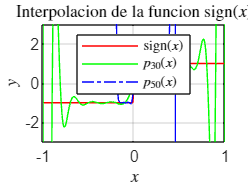

% Definimos los polinomios de Lagrange con puntos equiespaciados:

p10=interlagrange(linspace(-1,1,11),sign(linspace(-1,1,11)));
p20=interlagrange(linspace(-1,1,21),sign(linspace(-1,1,21)));
p30=interlagrange(linspace(-1,1,31),sign(linspace(-1,1,31)));
p40=interlagrange(linspace(-1,1,41),sign(linspace(-1,1,41)));
p50=interlagrange(linspace(-1,1,51),sign(linspace(-1,1,51)));
p60=interlagrange(linspace(-1,1,61),sign(linspace(-1,1,61)));
p70=interlagrange(linspace(-1,1,71),sign(linspace(-1,1,71)));
p80=interlagrange(linspace(-1,1,81),sign(linspace(-1,1,81)));
p90=interlagrange(linspace(-1,1,91),sign(linspace(-1,1,91)));


x=-1.5:0.01:1.5;
y=sign(x);
plot(x,y,'r', x,polyval(p30,x),'g', x,polyval(p50,x),'-.b','Linewidth',0.5)
%plot(x,y,'r', x,polyval(p20,x),'g', x,polyval(p80,x),'-.b','Linewidth',0.5)
axis([-1 1, -3, 3])
grid on
title('Interpolacion de la funcion sign$(x)$',...
    'Interpreter','latex')  % Fórmulas en LaTex
xlabel('$x$', 'Interpreter','latex')
ylabel('$y$', 'Interpreter','latex')
l=legend('sign$(x)$', '$p_{30}(x)$', '$p_{50}(x)$',...
     'Location','north');
set(l,'Interpreter','latex')

Error absoluto $|f(x)-p_n(x)|$ en $[-1,1],$ con nodos equiespaciados:

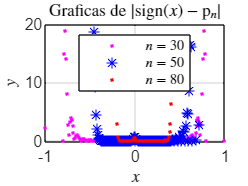

x=-1.5:0.01:1.5;                     
y30=abs(sign(x)-polyval(p30,x));
y50=abs(sign(x)-polyval(p50,x));
y80=abs(sign(x)-polyval(p80,x));
plot(x,y30,'.m',x,y50,'*b', x,y80,'.r','Linewidth', 0.5)
axis([-1 1, -0.25, 20])
grid on
title('Graficas de $|$sign$(x)-$p$_{n}|$',...
    'Interpreter','latex')  % Fórmulas en LaTex
xlabel('$x$', 'Interpreter','latex')
ylabel('$y$', 'Interpreter','latex')
lg=legend('$n=30$', '$n=50$', '$n=80$',...
     'Location','north');
set(lg,'Interpreter','latex')

**Ejercicio #2**

a) Vamos a interpolar la funcion $f(x) = e^x$ en el intervalo $[1,2]$ por medio de un polinomio interpolador de Lagrange y uno de Hermite. 

f=@(x) exp(x); I=[1 2];

% Nodos
X = [1 1.5 2]; Y = f(X);
Z = Y; % Ya que la derivada de e^x es e^x

% Polinomio p_2 interpolador de Lagrange
[pL2] = interlagrange(X,Y)

pL2 =    2.287919573427132  -2.192984449809792   2.623346704841705



% Polinomio h_5 interpolador de Hermite
[h5] = InterpoladorHermite(X, Y, Z)

h5 =    0.037794343649288  -0.093587330135051   0.458043463322497   0.167126285325480   1.195276470134104   0.953628596162446


b) Ahora calculemos cotas para los errores. En este ejercicio se puede ver que $M_n=e^2$ para cualquier $n\geq 1$ debido a que $f(x)=e^x.$

- ***Error Lagrange: ***


$$|f(x)-p_2(x)| \leq \frac{M_3}{3!} |(x-1)(x-1.5)(x-2)| = \frac{e^2}{6} |x^3-4.5x^2+6.5x-3|$$


Se puede comprobar que el valor máximo en $I$ del polinomio $|\pi_3(x)|$(los ceros de su derivada son $x=\frac{9 \pm \sqrt{3}}{6}$) es aproximadamente $0.048$. Luego,

$|f(x)-p_2(x)| \leq \frac{e^2}{6} (0.048) \approx 0.05911$.

- ***Error Hermite:***


$$|f(x)-h_5(x)| \leq \frac{M_6}{6!} (x-1)^2(x-1.5)^2(x-2)^2 = \frac{e^2}{720} (x^6 - 9 x^5 + 33.25 x^4 - 64.5 x^3 + 69.25 x^2 - 39 x + 9)$$


Los ceros de $(\pi_3(x))^2$ son $x=1, 2, \frac{3}{2}, \frac{9\pm \sqrt{3}}{6}$, y se puede comprobar que el valor máximo en $I$ es aproximadamente $1.7887$. Entonces,


$$|f(x)-h_5(x)| \leq \frac{M_6}{6!} (x-1)^2(x-1.5)^2(x-2)^2 = \frac{e^2}{720} (0.002314) \approx 2.3747 \times 10^{-5}$$


c) Veamos la situacion anterior de maner grafica.

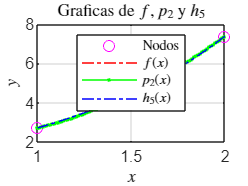

x=1:0.01:2;
x1=X;
y1=Y;
y=exp(x);
plot(x1, y1, 'mo', x,y,'r-.', x,polyval(pL2,x),'g.-', ...
    x,polyval(h5,x),'b-.','Linewidth',0.5)
%axis([1 4 -1 'inf'])
grid on
title('Graficas de $f$, $p_{2}$ y $h_{5}$',...
    'Interpreter','latex')  % Fórmulas en LaTex
xlabel('$x$', 'Interpreter','latex')
ylabel('$y$', 'Interpreter','latex')
lg=legend('Nodos', '$f(x)$', '$p_2(x)$', '$h_5(x)$', ...
    'Location','north');
set(lg,'Interpreter','latex')

Gráficamente podemos apreciar que $h_5$ se aproxima mejor que $p_2$ a $f$, lo cual se mostró también en el inciso b) con el cálculo de cotas para los errores teóricos. 

**Ejercicio #3**

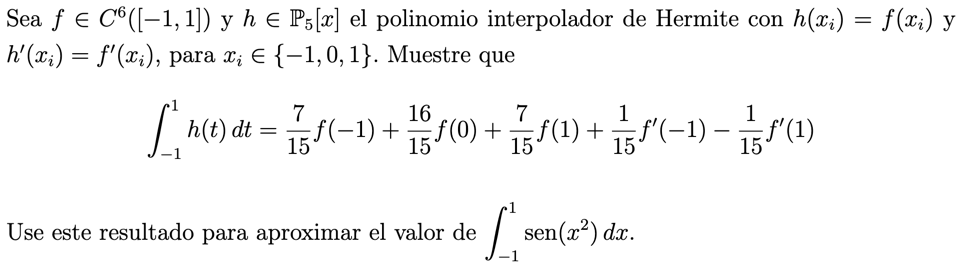

Sean $x_0=-1, \quad x_1=0, \quad x_2=1.$ El polinomio de interpolación de Hermite es


$$\[ h_5(x)= f(-1) H_0(x) + f'(-1) K_0(x) + f(0)H_1(x) + f'(0) K_1(x) + f(1)H_2(x) + f'(1) K_2(x) \]

\[
\Rightarrow \int_{-1}^1 h_5(x) \, dx = 
 f(-1) \int_{-1}^1 H_0(x)\, dx + f'(-1) \int_{-1}^1  K_0(x) \, dx + f(0) \int_{-1}^1 H_1(x)\, dx + f'(0) \int_{-1}^1  K_1(x) \, dx  \]
\[ + f(1) \int_{-1}^1 H_2(x) \,dx + f'(1) \int_{-1}^1 K_2(x) \, dx \]$$


Los polinomios $H_i, K_i$ los podemos calcular con $\texttt{MATLAB}$ con el script que creamos:

format rat;
x=[-1 0 1];
[H0, K0] = HkKk(1, x)

H0 =        3/4           -1/2           -5/4            1              0              0       


K0 =        1/4           -1/4           -1/4            1/4            0              0       


[H1, K1] = HkKk(2, x)

H1 =        0              1              0             -2              0              1       


K1 =        1              0             -2              0              1              0       


[H2, K2] = HkKk(3, x)

H2 =       -3/4           -1/2            5/4            1              0              0       


K2 =        1/4            1/4           -1/4           -1/4            0              0       



% Integrales definidas de estos polinomios en [-1,1], usamos una función
% nueva llamada Integralpoly

[IH0]= Integralpoly(H0,-1,1)

IH0 =        7/15    


[IH1]= Integralpoly(H1,-1,1)

IH1 =       16/15    


[IH2]= Integralpoly(H2,-1,1)

IH2 =        7/15    



[IK0]= Integralpoly(K0,-1,1)

IK0 =        1/15    


[IK1]= Integralpoly(K1,-1,1)

IK1 =        0       


[IK2]= Integralpoly(K2,-1,1)

IK2 =       -1/15    


Entonces tenemos que 


$$\int_{-1}^1 h_5(x) \, dx = f(-1) \cdot \frac{7}{15} +f'(-1) \cdot \frac{1}{15} + f(0)\cdot \frac{16}{15} + f'(0) \cdot 0 + f(1) \cdot \frac{7}{15} + f'(1) \cdot \frac{-1}{15}$$


lo cual coincide con la fórmula. 

Con base en lo anterior,


$$\[ \int_{-1}^1 \sin(x^2) \, dx \approx \frac{7}{15} \sin(1) + \frac{16}{15} \sin(0) + \frac{7}{15} \sin(1) + \frac{1}{15} \cdot 2(-1)\cdot \cos(1) - \frac{1}{15} \cdot 2(1) \cdot \cos(1) \]

\[\approx 0.6412923043  \]$$


Podemos realizar el cálculo "exacto" de la siguiente manera:

format long;
I_exacta=integral(@(x) sin(x.^2), -1, 1)

I_exacta =    0.620536603446762


**Ejercicio #4**

Vamos a ver el siguiente ejemplo y luego utilizar la funcion $\texttt{I = adaptativeSimpson(f, a, b, tol)}$para comparar los resultados. 

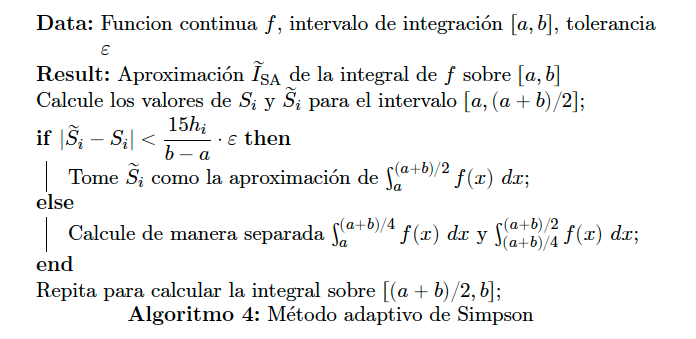

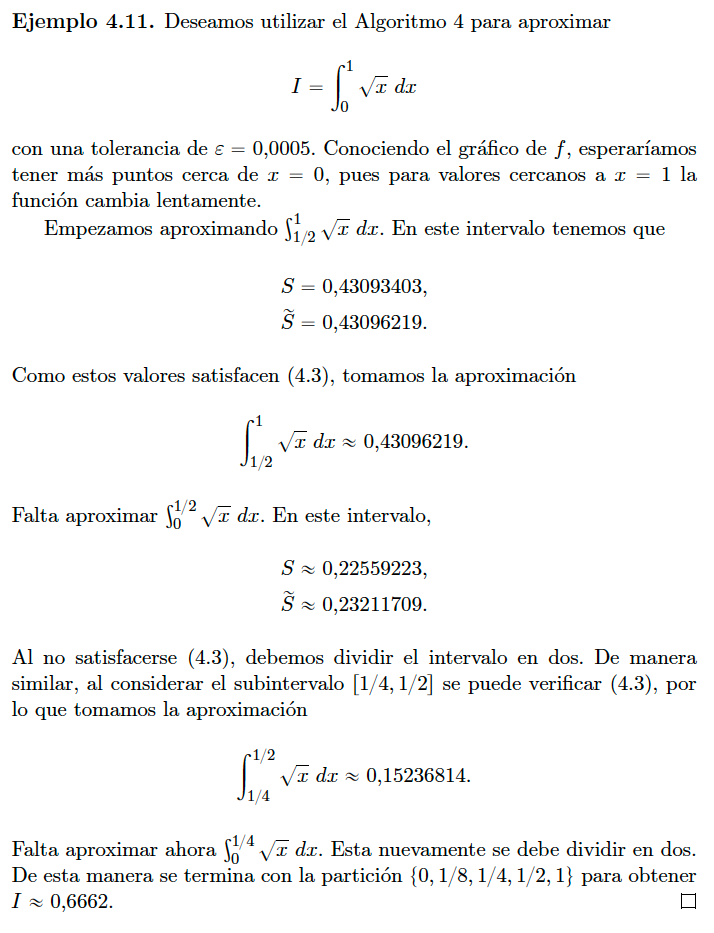

f = @(x) sqrt(x);
a = 0; b = 1;
tol = 5e-4;

disp('===============================')

disp('Metodo adaptativo de Simpson:')

Metodo adaptativo de Simpson:


disp('===============================')

I = adaptativeSimpson(f, a, b, tol)

I =    0.666663133781794


## **Funciones**

***Polinomios cardinales de Lagrange:***

function [c]=Lk(k,x)
%Polinomio Lk cardinal de Lagrange
npts=length(x);
c=1;
for i=[1:(k-1), (k+1):npts] %i \neq k
    den = x(k) - x(i);
    c = conv(c, [1/den, - x(i)/den]);
end
end

***Polinomio interpolador de Lagrange:***

function [c] = interlagrange(x,y)
npts=length(x);     %cantidad de puntos: n+1
c=0;
for k=1:npts
    c = c + Lk(k,x)*y(k);
end
end

***Polinomios cardinales de Hermite***

function [Hk, Kk] = HkKk(k, x)
    % Determinar el correspondiente polinomio de Lagrange
    Lx = Lk(k, x);
    % Evaluar la derivada xk
    dLx = polyval(polyder(Lx), x(k) );
    % Calcular Lk^2
    Lx2 = conv(Lx, Lx);
    % Determinar el polinomio Hk
    q = [-2*dLx, 1 + 2*dLx*x(k)];
    Hk = conv(Lx2, q);
    % Deterimar el polinomio Kk
    q = [1, -x(k)];
    Kk = conv(Lx2, q);
end

***Polinomio interpolador de Hermite***

function [c] = InterpoladorHermite(x, y, z)
    nPts = length(x); % Cantidad de puntos: n+1
    c = 0;
    for k = 1 : nPts
        % Calcular polinomios de Hermite
        [Hk, Kk] = HkKk(k,x);
        % Acumular al polinomio interpolador
        c = c + Hk * y(k) + Kk * z(k);
    end
end

***Integral definida de polinomios***

function [Int]= Integralpoly(p,a,b)
% Inputs: polimonio p, intervalo [a,b]
% Output: integral definida de p en [a,b]
q = polyint(p);
Int = diff(polyval(q,[a b]));
end

***Metodo adaptativo de Simpson para aproximar integrales***

function I = adaptativeSimpson(f, a, b, tol)
% Calcula la integral de f en [a, b] con tolerancia tol utilizando el método adaptativo de Simpson.

% Calcula el valor de la función en los extremos del intervalo.
fa = f(a);
fb = f(b);

% Calcula el valor de la función en el punto medio del intervalo.
c = (a + b) / 2;
fc = f(c);

% Calcula la aproximación inicial de la integral usando la regla de Simpson.
h = (b - a) / 6;
integral_approx = h * (fa + 4 * fc + fb);

% Calcula la aproximación de la integral usando la regla de Simpson en dos subintervalos.
d = (a + c) / 2;
fd = f(d);
e = (c + b) / 2;
fe = f(e);

h2 = (c - a) / 6;
h3 = (b - c) / 6;

integral_approx2 = h2 * (fa + 4 * fd + fc);
integral_approx3 = h3 * (fc + 4 * fe + fb);

% Calcula la estimación del error relativo.
error = abs(integral_approx2 + integral_approx3 - integral_approx);

% Compara el error relativo con la tolerancia especificada.
if error <= tol
    I = integral_approx2 + integral_approx3;
else
    % Divide el intervalo en dos y recursivamente aplica el método a cada subintervalo.
    left_result = adaptativeSimpson(f, a, c, tol / 2);
    right_result = adaptativeSimpson(f, c, b, tol / 2);
    I = left_result + right_result;
end
end
